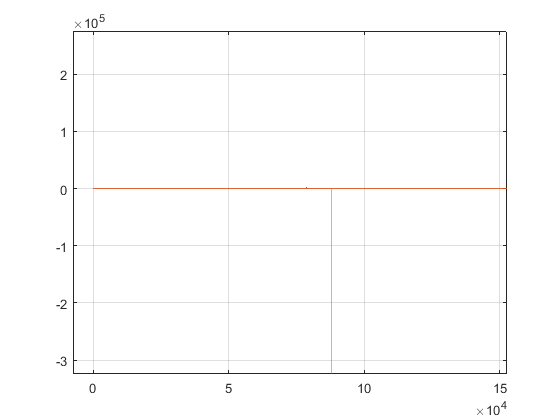

cntRef = 1:50000;

cntV = [dataLOG.GPS.Count];
[cntVUnique, index] = unique(cntV);

mesVn = [dataLOG.GPS.V_north];
mesVe = [dataLOG.GPS.V_east];


vNInt = interp1(cntVUnique, mesVn(index), cntRef, 'linear');
plot(cntRef, vNInt);
hold on; grid on;
plot(cntV, mesVn);